#  034IN "Fundamentals of Automatic Control" - Introduction to MATLAB/Simulink Hands On: State Space Descriptions

## Introduction

This live script illustrates some models of dynamical systems (linear or nonlinear, time-invariant or time-variant, continuous or discrete time). 

Inspired by the examples illustrated in the live script [StateSpaceDescriptionExamples.mlx](matlab:open('./StateSpaceDescriptionExamples.mlx')), you  will able to create a Matlab live script and a Simulink model working together in order to simulate the behavior of a continuous time or discrete time dynamical system.

What you will learn: 

- Given a state space description of a dynamical system, how to build a Simulink model for such a system;

- Tune a Simulink model, setting the model parameters (or the simulation parameters) using a Matlab script;

- How to run a Simulink model and retrieve the results using a Matlab script.

## A Linear Continuous Time System: a Mechanical System

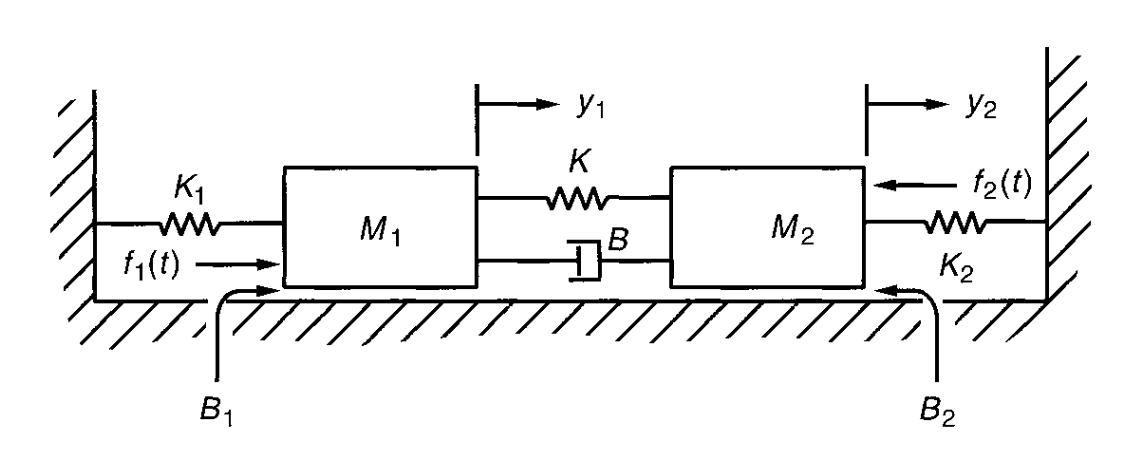

 The dynamics of the system is given by the state-space model derived from conservation balances (of mass, energy, etc.). Applying Newton's second law, we obtain the following state-space description:


$$\left\{ \begin{array}{lcl}
\left[ \begin{array}{c}
\dot{x}_1(t) \\ \dot{x}_2(t) \\ \dot{x}_3(t) \\ \dot{x}_4 (t)
\end{array} \right] &=& \left[ \begin{array}{cccc} 
0 & 1 & 0 & 0 \\[0.5em]
-\displaystyle \frac{K_1+K}{M_1} & -\displaystyle \frac{B_1+B}{M_1} & \displaystyle \frac{K}{M_1} & \displaystyle \frac{B}{M_1} \\[0.5em]
0 & 0 & 0 & 1 \\[0.5em]
 \displaystyle \frac{K}{M_2} & \displaystyle \frac{B}{M_2} &-\displaystyle \frac{K_2+K}{M_2} & -\displaystyle \frac{B_2+B}{M_2}
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] \, + \, 
\left[ \begin{array}{cc}
0 & 0 \\[0.5em]
\displaystyle \frac{1}{M_1} & 0 \\[0.5em]
0 & 0 \\[0.5em]
0 & \displaystyle -\frac{1}{M_2} 
\end{array} \right] \, \left[ \begin{array}{c}
f_1(t) \\[0.5em]
f_2(t) 
\end{array} \right] \\[0.75em] \\
\left[ \begin{array}{c}
y_1(t) \\[0.5em]
y_2(t) 
\end{array} \right] &=& \left[ \begin{array}{cccc}
1 & 0 & 0 &0\\[0.5em]
0 & 0 & 1 & 0
\end{array} \right] \, \left[ \begin{array}{c}
x_1(t) \\ x_2(t) \\ x_3(t) \\ x_4 (t)
\end{array} \right] 
\end{array} \right.$$


where the state variables are


$$\left\{ \begin{array}{lcl}
x_1(t) &=& y_1(t) \\
x_2(t) &=& \dot{y}_1(t) \\
x_3(t) &=& y_2(t) \\
x_4(t) &=& \dot{y}_2(t)
\end{array} \right.$$


This state-space description may be easily implemented in Matlab.

**Proposal**: implement a model using a Matlab live script to analyse the evolution of the above described mechanical system. Use the following parameters to configure tthe system model:

- point masses [kg]: $M_1 = 1.0$ , and $M_2 = 2.5$;

- viscous damping coefficients [N s/m]: $B = 3.60 \cdot 10^{-3}\, , \quad B_1 = 5.0 \cdot 10^{-2}\, , \quad B_2 = 5.0 \cdot 10^{-2}\$;

- spring constants [N/m] : $K = 9.1 \cdot 10^{-2}\, , \quad K_1 = 1.0 \cdot 10^{-1}\, , \quad K_2 = 1.0 \cdot 10^{-1}$;

- initial conditions: $x(0) = \left[ \begin{array}{cccc} 1.0 & 0 & -0.5 & 0 \end{array} \right]^{T}$

- external forces (inputs): $f_1(t) = 2 \cdot 1(t) \;, \quad f_2(t) = -2 \cdot 1(t-10)$

- simulation time interval [s]: $t \in \left[ 0 \, , 30\right]$

% Create a state-space description using the MATLAB ode() function, then 
% assign the model parameters, the initial state, the simulation configuration. 
% Using the same live script, run the simulation, retrieve the result
% and plot the state and output movements.

More exercises available soon.